# Atividade Avaliativa - Denavit-Hartemberg e RoKiSim

Nomes: Alexandre Reis Francisco Júnior e Juan Pablo de Almeida Carvalho

Data: 18/05/2026

% Limpeza da Área de Trabalho
clc; close all; clear all;

## Manipulador Staubli TX40

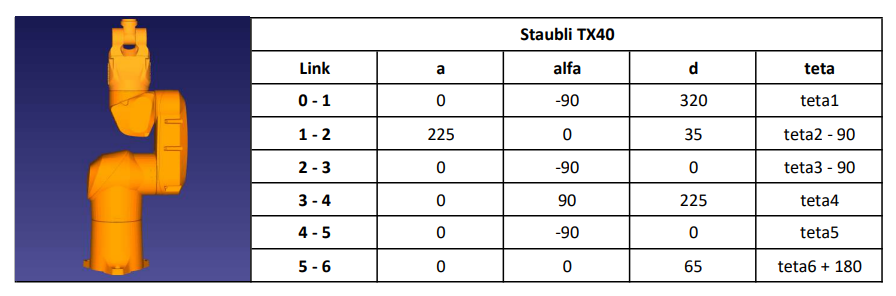

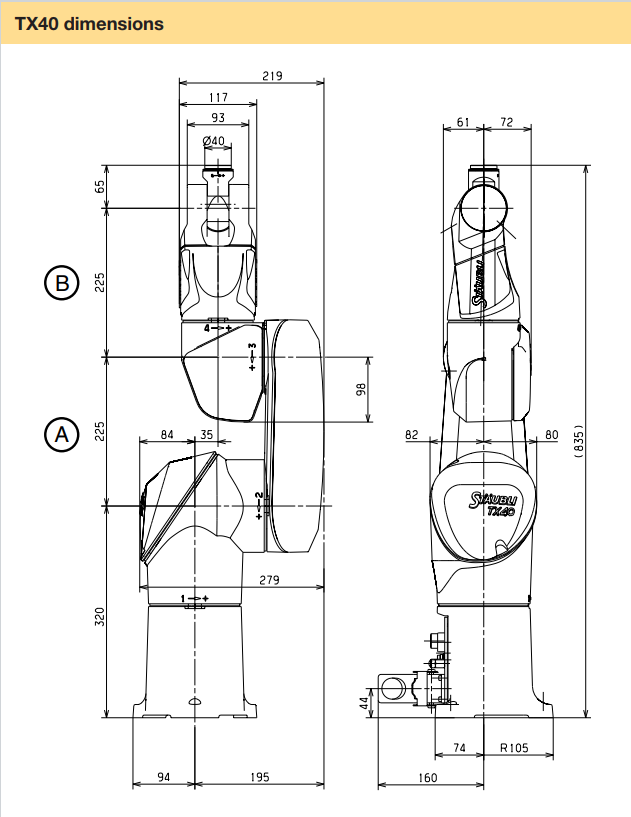

% Validação 1 (angulos iguais a zero):
teta1 = 0;
teta2 = 0;
teta3 = 0;
teta4 = 0;
teta5 = 0;
teta6 = 0;
fprintf('Staubli TX40 - Validação 1 \n');

Staubli TX40 - Validação 1 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = 0 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = 0 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais TX40 (Validação 1):')

Matrizes parciais TX40 (Validação 1):


% Matriz parcial 0-1:
TX40_1_dh_01 = denavit(0, -90, 320, teta1)

TX40_1_dh_01 =      1     0     0     0
     0     0     1     0
     0    -1     0   320
     0     0     0     1



% Matriz parcial 1-2:
TX40_1_dh_12 = denavit(225, 0, 35, teta2-90)

TX40_1_dh_12 =      0     1     0     0
    -1     0     0  -225
     0     0     1    35
     0     0     0     1



% Matriz parcial 2-3:
TX40_1_dh_23 = denavit(0, -90, 0, teta3-90)

TX40_1_dh_23 =      0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 3-4:
TX40_1_dh_34 = denavit(0, 90, 225, teta4)

TX40_1_dh_34 =      1     0     0     0
     0     0    -1     0
     0     1     0   225
     0     0     0     1



% Matriz parcial 4-5:
TX40_1_dh_45 = denavit(0, -90, 0, teta5)

TX40_1_dh_45 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 5-6:
TX40_1_dh_56 = denavit(0, 0, 65, teta6+180)

TX40_1_dh_56 =     -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante Staubli TX40 (Validação 1):')

Matriz Resultante Staubli TX40 (Validação 1):


TX40_1_MR = TX40_1_dh_01 * TX40_1_dh_12 * TX40_1_dh_23 * TX40_1_dh_34 * TX40_1_dh_45 * TX40_1_dh_56

TX40_1_MR =      1     0     0     0
     0     1     0    35
     0     0     1   835
     0     0     0     1


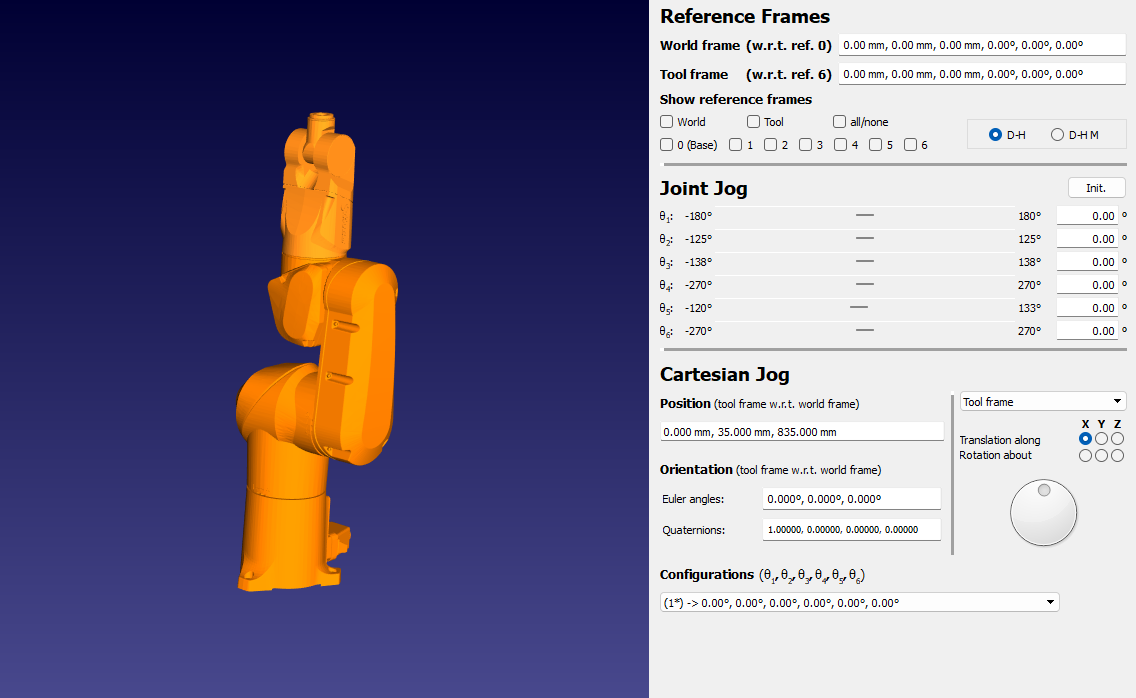

% Validação 2 (angulos teta3 = 45 e teta5 = -90):
teta1 = 0;
teta2 = 0;
teta3 = 45;
teta4 = 0;
teta5 = -90;
teta6 = 0;
fprintf('Staubli TX40 - Validação 2 \n');

Staubli TX40 - Validação 2 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = 45 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = -90 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais TX40 (Validação 2):')

Matrizes parciais TX40 (Validação 2):


% Matriz parcial 0-1:
TX40_2_dh_01 = denavit(0, -90, 320, teta1)

TX40_2_dh_01 =      1     0     0     0
     0     0     1     0
     0    -1     0   320
     0     0     0     1



% Matriz parcial 1-2:
TX40_2_dh_12 = denavit(225, 0, 35, teta2-90)

TX40_2_dh_12 =      0     1     0     0
    -1     0     0  -225
     0     0     1    35
     0     0     0     1



% Matriz parcial 2-3:
TX40_2_dh_23 = denavit(0, -90, 0, teta3-90)

TX40_2_dh_23 =     0.7071         0    0.7071         0
   -0.7071         0    0.7071         0
         0   -1.0000         0         0
         0         0         0    1.0000



% Matriz parcial 3-4:
TX40_2_dh_34 = denavit(0, 90, 225, teta4)

TX40_2_dh_34 =      1     0     0     0
     0     0    -1     0
     0     1     0   225
     0     0     0     1



% Matriz parcial 4-5:
TX40_2_dh_45 = denavit(0, -90, 0, teta5)

TX40_2_dh_45 =      0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 5-6:
TX40_2_dh_56 = denavit(0, 0, 65, teta6+180)

TX40_2_dh_56 =     -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante Staubli TX40 (Validação 2):')

Matriz Resultante Staubli TX40 (Validação 2):


TX40_2_MR = TX40_2_dh_01 * TX40_2_dh_12 * TX40_2_dh_23 * TX40_2_dh_34 * TX40_2_dh_45 * TX40_2_dh_56

TX40_2_MR =     0.7071         0   -0.7071  113.1371
         0    1.0000         0   35.0000
    0.7071         0    0.7071  750.0610
         0         0         0    1.0000


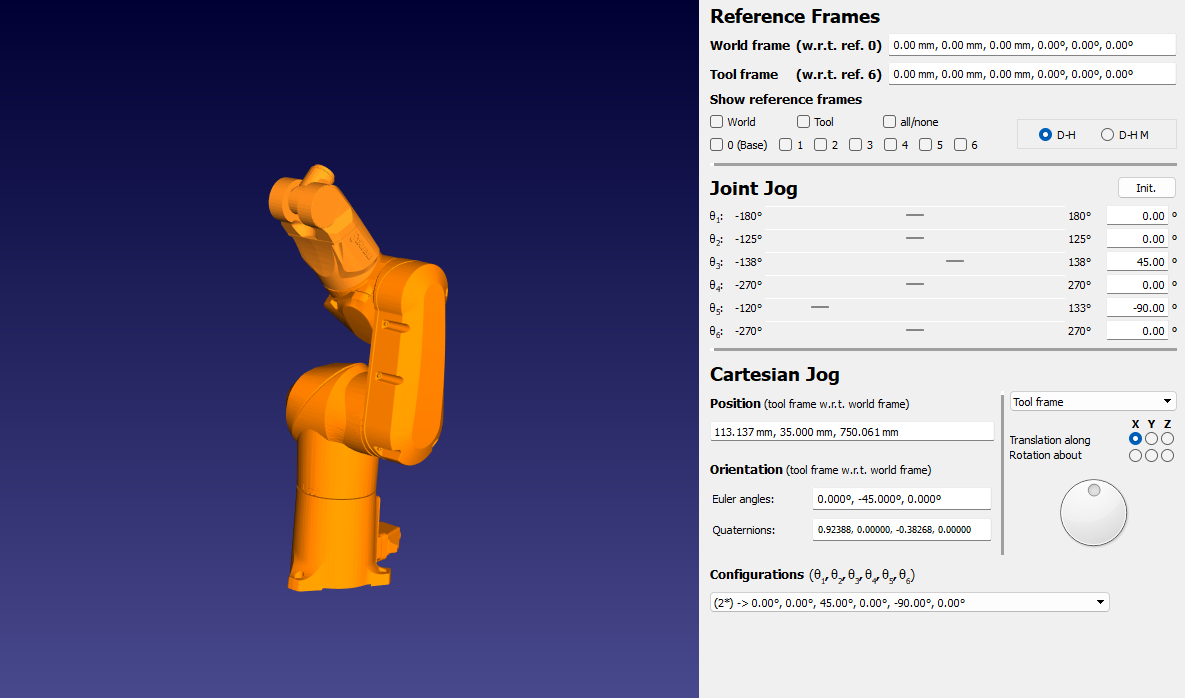

## Manipulador Omron Adept Viper s650

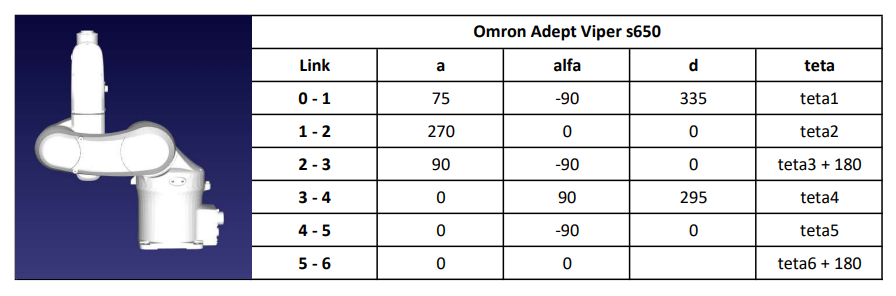

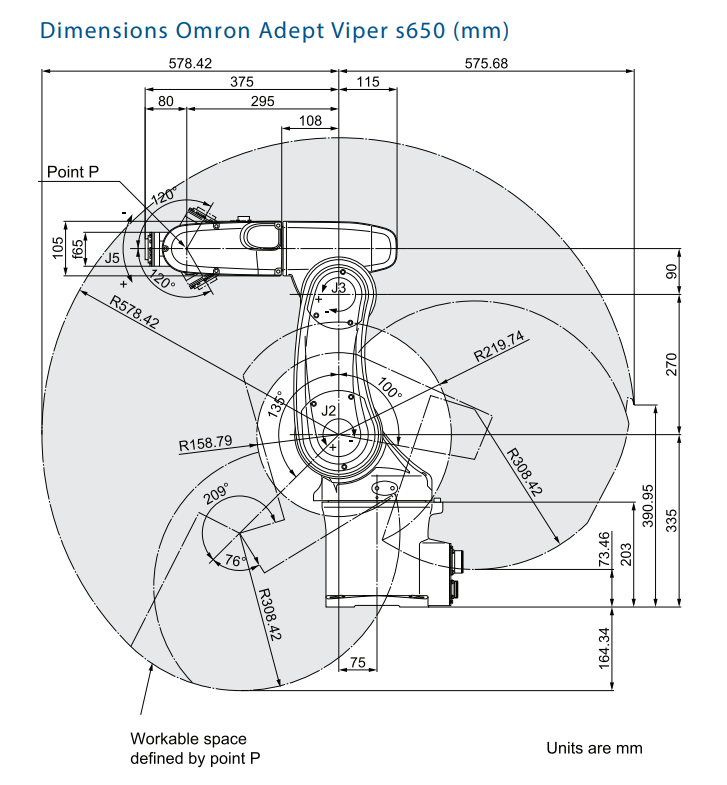

% Validação 1 (angulos iguais a zero):
teta1 = 0;
teta2 = 0;
teta3 = 0;
teta4 = 0;
teta5 = 0;
teta6 = 0;
fprintf('Omron Adept Viper s650 - Validação 1 \n');

Omron Adept Viper s650 - Validação 1 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = 0 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = 0 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais s650 (Validação 1):')

Matrizes parciais s650 (Validação 1):


% Matriz parcial 0-1:
s650_1_dh_01 = denavit(75, -90, 335, teta1)

s650_1_dh_01 =      1     0     0    75
     0     0     1     0
     0    -1     0   335
     0     0     0     1



% Matriz parcial 1-2:
s650_1_dh_12 = denavit(270, 0, 0, teta2)

s650_1_dh_12 =      1     0     0   270
     0     1     0     0
     0     0     1     0
     0     0     0     1



% Matriz parcial 2-3:
s650_1_dh_23 = denavit(90, -90, 0, teta3+180)

s650_1_dh_23 =     -1     0     0   -90
     0     0    -1     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 3-4:
s650_1_dh_34 = denavit(0, 90, 295, teta4)

s650_1_dh_34 =      1     0     0     0
     0     0    -1     0
     0     1     0   295
     0     0     0     1



% Matriz parcial 4-5:
s650_1_dh_45 = denavit(0, -90, 0, teta5)

s650_1_dh_45 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 5-6:
s650_1_dh_56 = denavit(0, 0, 80, teta6+180)

s650_1_dh_56 =     -1     0     0     0
     0    -1     0     0
     0     0     1    80
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante Omron Adept Viper s650 (Validação 1):')

Matriz Resultante Omron Adept Viper s650 (Validação 1):


s650_1_MR = s650_1_dh_01 * s650_1_dh_12 * s650_1_dh_23 * s650_1_dh_34 * s650_1_dh_45 * s650_1_dh_56

s650_1_MR =      1     0     0   255
     0     1     0     0
     0     0     1   710
     0     0     0     1


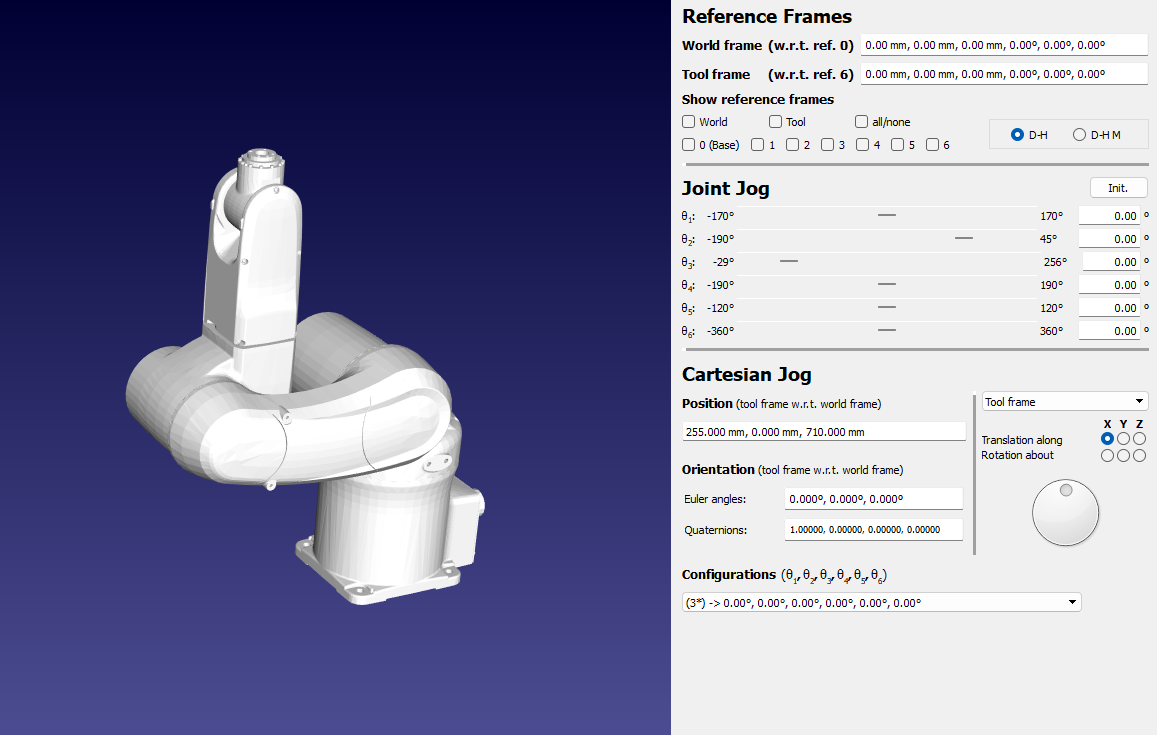

% Validação 2 (angulos teta3 = -20 e teta5 = 80):
teta1 = 0;
teta2 = 0;
teta3 = -20;
teta4 = 0;
teta5 = 80;
teta6 = 0;
fprintf('Omron Adept Viper s650 - Validação 2 \n');

Omron Adept Viper s650 - Validação 2 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = -20 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = 80 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais s650 (Validação 2):')

Matrizes parciais s650 (Validação 2):


% Matriz parcial 0-1:
s650_2_dh_01 = denavit(75, -90, 335, teta1)

s650_2_dh_01 =      1     0     0    75
     0     0     1     0
     0    -1     0   335
     0     0     0     1



% Matriz parcial 1-2:
s650_2_dh_12 = denavit(270, 0, 0, teta2)

s650_2_dh_12 =      1     0     0   270
     0     1     0     0
     0     0     1     0
     0     0     0     1



% Matriz parcial 2-3:
s650_2_dh_23 = denavit(90, -90, 0, teta3+180)

s650_2_dh_23 =    -0.9397         0   -0.3420  -84.5723
    0.3420         0   -0.9397   30.7818
         0   -1.0000         0         0
         0         0         0    1.0000



% Matriz parcial 3-4:
s650_2_dh_34 = denavit(0, 90, 295, teta4)

s650_2_dh_34 =      1     0     0     0
     0     0    -1     0
     0     1     0   295
     0     0     0     1



% Matriz parcial 4-5:
s650_2_dh_45 = denavit(0, -90, 0, teta5)

s650_2_dh_45 =     0.1736         0   -0.9848         0
    0.9848         0    0.1736         0
         0   -1.0000         0         0
         0         0         0    1.0000



% Matriz parcial 5-6:
s650_2_dh_56 = denavit(0, 0, 80, teta6+180)

s650_2_dh_56 =     -1     0     0     0
     0    -1     0     0
     0     0     1    80
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante Omron Adept Viper s650 (Validação 2):')

Matriz Resultante Omron Adept Viper s650 (Validação 2):


s650_2_MR = s650_2_dh_01 * s650_2_dh_12 * s650_2_dh_23 * s650_2_dh_34 * s650_2_dh_45 * s650_2_dh_56

s650_2_MR =     0.5000         0    0.8660  228.8138
         0    1.0000         0         0
   -0.8660         0    0.5000  621.4275
         0         0         0    1.0000


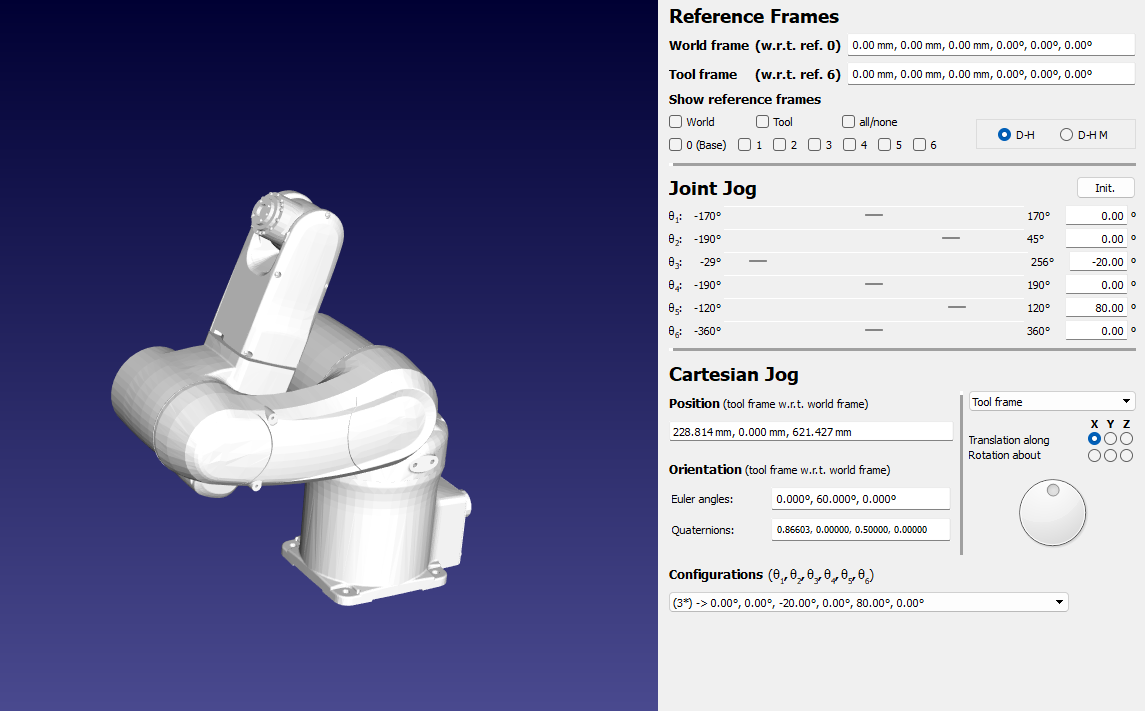

## Manipulador ABB IRB140

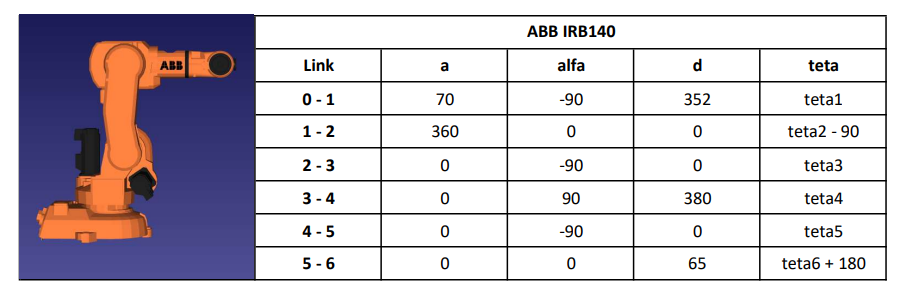

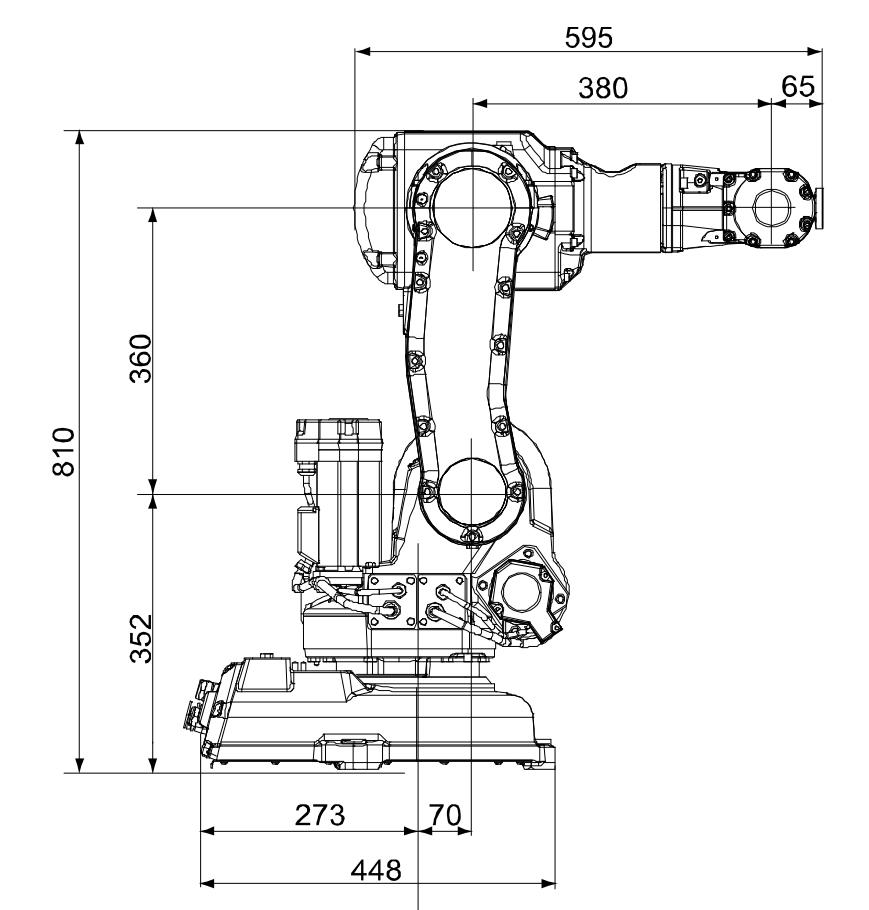

% Validação 1 (angulos iguais a zero):
teta1 = 0;
teta2 = 0;
teta3 = 0;
teta4 = 0;
teta5 = 0;
teta6 = 0;
fprintf('ABB IRB140 - Validação 1 \n');

ABB IRB140 - Validação 1 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = 0 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = 0 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais IRB140 (Validação 1):')

Matrizes parciais IRB140 (Validação 1):


% Matriz parcial 0-1:
IRB140_1_dh_01 = denavit(70, -90, 352, teta1)

IRB140_1_dh_01 =      1     0     0    70
     0     0     1     0
     0    -1     0   352
     0     0     0     1



% Matriz parcial 1-2:
IRB140_1_dh_12 = denavit(360, 0, 0, teta2-90)

IRB140_1_dh_12 =      0     1     0     0
    -1     0     0  -360
     0     0     1     0
     0     0     0     1



% Matriz parcial 2-3:
IRB140_1_dh_23 = denavit(0, -90, 0, teta3)

IRB140_1_dh_23 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 3-4:
IRB140_1_dh_34 = denavit(0, 90, 380, teta4)

IRB140_1_dh_34 =      1     0     0     0
     0     0    -1     0
     0     1     0   380
     0     0     0     1



% Matriz parcial 4-5:
IRB140_1_dh_45 = denavit(0, -90, 0, teta5)

IRB140_1_dh_45 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 5-6:
IRB140_1_dh_56 = denavit(0, 0, 65, teta6+180)

IRB140_1_dh_56 =     -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante ABB IRB140 (Validação 1):')

Matriz Resultante ABB IRB140 (Validação 1):


IRB140_1_MR = IRB140_1_dh_01 * IRB140_1_dh_12 * IRB140_1_dh_23 * IRB140_1_dh_34 * IRB140_1_dh_45 * IRB140_1_dh_56

IRB140_1_MR =      0     0     1   515
     0     1     0     0
    -1     0     0   712
     0     0     0     1


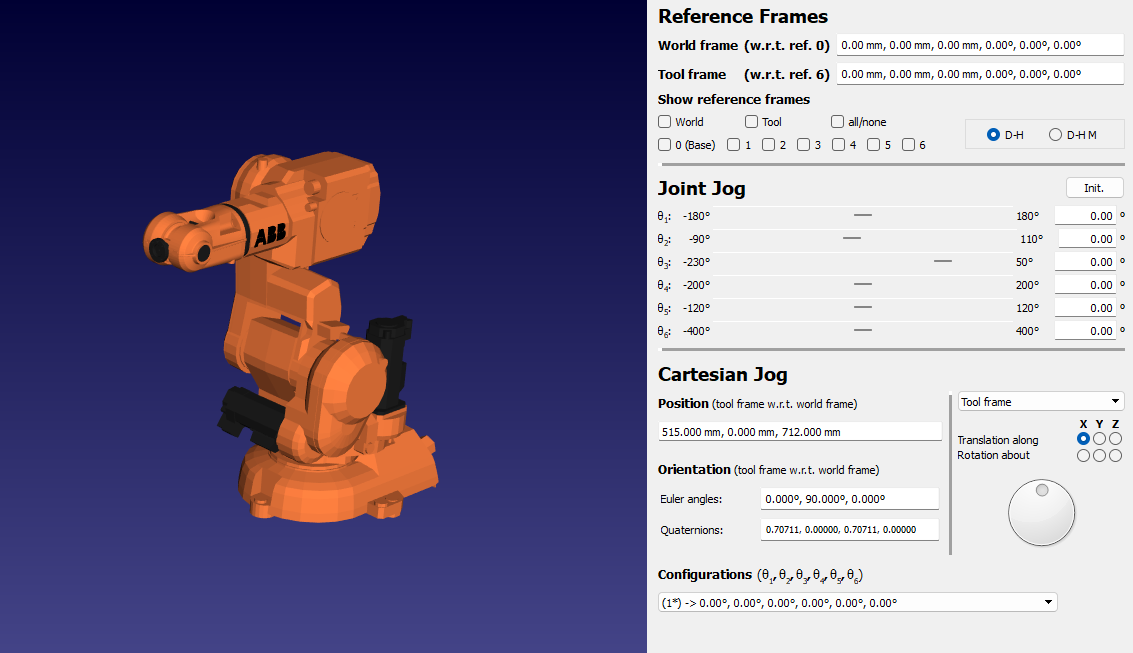

% Validação 2 (angulos teta3 = 45 e teta5 = -90):
teta1 = 0;
teta2 = 0;
teta3 = 45;
teta4 = 0;
teta5 = -90;
teta6 = 0;
fprintf('ABB IRB140 - Validação 2 \n');

ABB IRB140 - Validação 2 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = 45 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = -90 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais IRB140 (Validação 2):')

Matrizes parciais IRB140 (Validação 2):


% Matriz parcial 0-1:
IRB140_2_dh_01 = denavit(70, -90, 352, teta1)

IRB140_2_dh_01 =      1     0     0    70
     0     0     1     0
     0    -1     0   352
     0     0     0     1



% Matriz parcial 1-2:
IRB140_2_dh_12 = denavit(360, 0, 0, teta2-90)

IRB140_2_dh_12 =      0     1     0     0
    -1     0     0  -360
     0     0     1     0
     0     0     0     1



% Matriz parcial 2-3:
IRB140_2_dh_23 = denavit(0, -90, 0, teta3)

IRB140_2_dh_23 =     0.7071         0   -0.7071         0
    0.7071         0    0.7071         0
         0   -1.0000         0         0
         0         0         0    1.0000



% Matriz parcial 3-4:
IRB140_2_dh_34 = denavit(0, 90, 380, teta4)

IRB140_2_dh_34 =      1     0     0     0
     0     0    -1     0
     0     1     0   380
     0     0     0     1



% Matriz parcial 4-5:
IRB140_2_dh_45 = denavit(0, -90, 0, teta5)

IRB140_2_dh_45 =      0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 5-6:
IRB140_2_dh_56 = denavit(0, 0, 65, teta6+180)

IRB140_2_dh_56 =     -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante ABB IRB140 (Validação 2):')

Matriz Resultante ABB IRB140 (Validação 2):


IRB140_2_MR = IRB140_2_dh_01 * IRB140_2_dh_12 * IRB140_2_dh_23 * IRB140_2_dh_34 * IRB140_2_dh_45 * IRB140_2_dh_56

IRB140_2_MR =     0.7071         0    0.7071  384.6625
         0    1.0000         0         0
   -0.7071         0    0.7071  489.2614
         0         0         0    1.0000


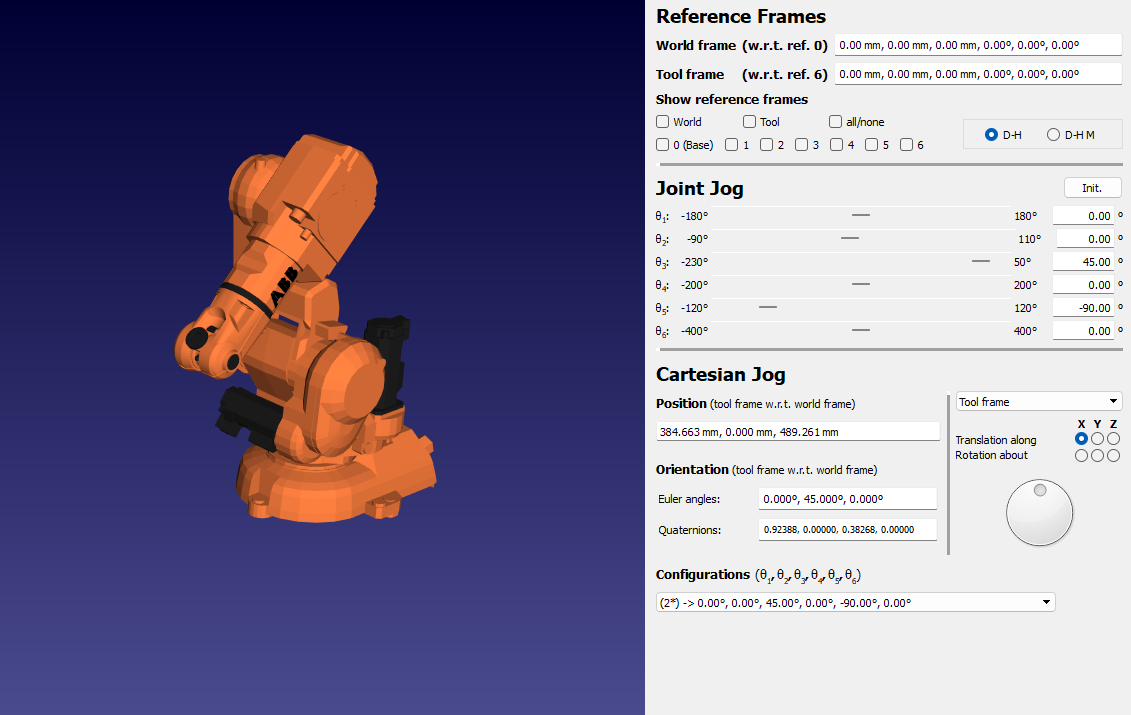

## Manipulador ABB IRB4400

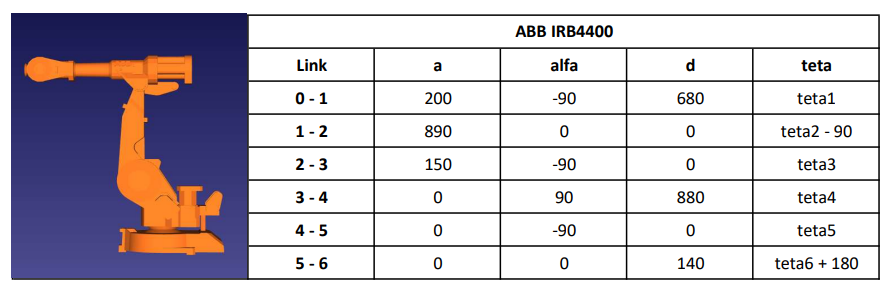

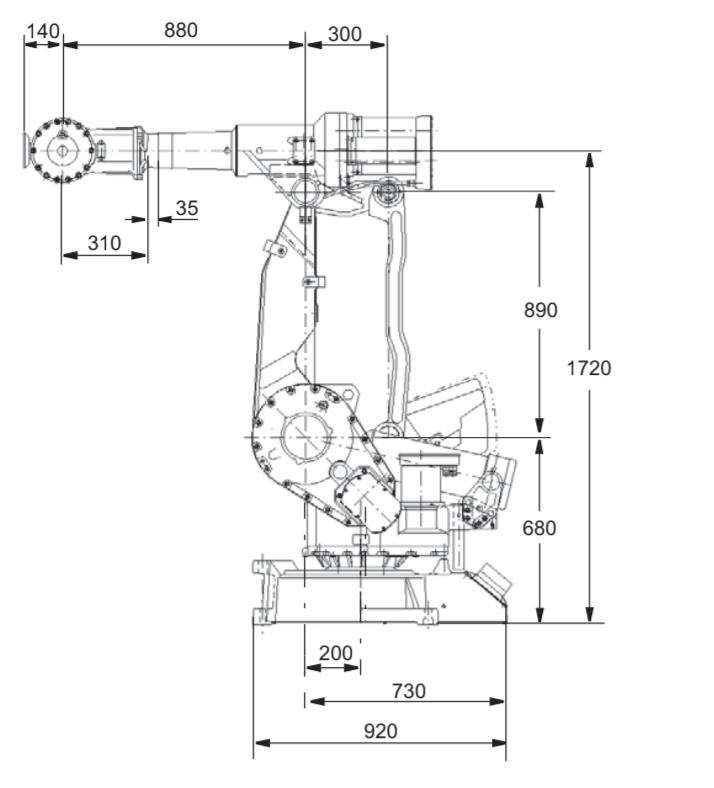

% Validação 1 (angulos iguais a zero):
teta1 = 0;
teta2 = 0;
teta3 = 0;
teta4 = 0;
teta5 = 0;
teta6 = 0;
fprintf('ABB IRB4400 - Validação 1 \n');

ABB IRB4400 - Validação 1 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = 0 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = 0 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais IRB4400 (Validação 1):')

Matrizes parciais IRB4400 (Validação 1):


% Matriz parcial 0-1:
IRB4400_1_dh_01 = denavit(200, -90, 680, teta1)

IRB4400_1_dh_01 =      1     0     0   200
     0     0     1     0
     0    -1     0   680
     0     0     0     1



% Matriz parcial 1-2:
IRB4400_1_dh_12 = denavit(890, 0, 0, teta2-90)

IRB4400_1_dh_12 =      0     1     0     0
    -1     0     0  -890
     0     0     1     0
     0     0     0     1



% Matriz parcial 2-3:
IRB4400_1_dh_23 = denavit(150, -90, 0, teta3)

IRB4400_1_dh_23 =      1     0     0   150
     0     0     1     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 3-4:
IRB4400_1_dh_34 = denavit(0, 90, 880, teta4)

IRB4400_1_dh_34 =      1     0     0     0
     0     0    -1     0
     0     1     0   880
     0     0     0     1



% Matriz parcial 4-5:
IRB4400_1_dh_45 = denavit(0, -90, 0, teta5)

IRB4400_1_dh_45 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 5-6:
IRB4400_1_dh_56 = denavit(0, 0, 140, teta6+180)

IRB4400_1_dh_56 =     -1     0     0     0
     0    -1     0     0
     0     0     1   140
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante ABB IRB4400 (Validação 1):')

Matriz Resultante ABB IRB4400 (Validação 1):


IRB4400_1_MR = IRB4400_1_dh_01 * IRB4400_1_dh_12 * IRB4400_1_dh_23 * IRB4400_1_dh_34 * IRB4400_1_dh_45 * IRB4400_1_dh_56

IRB4400_1_MR =            0           0           1        1220
           0           1           0           0
          -1           0           0        1720
           0           0           0           1


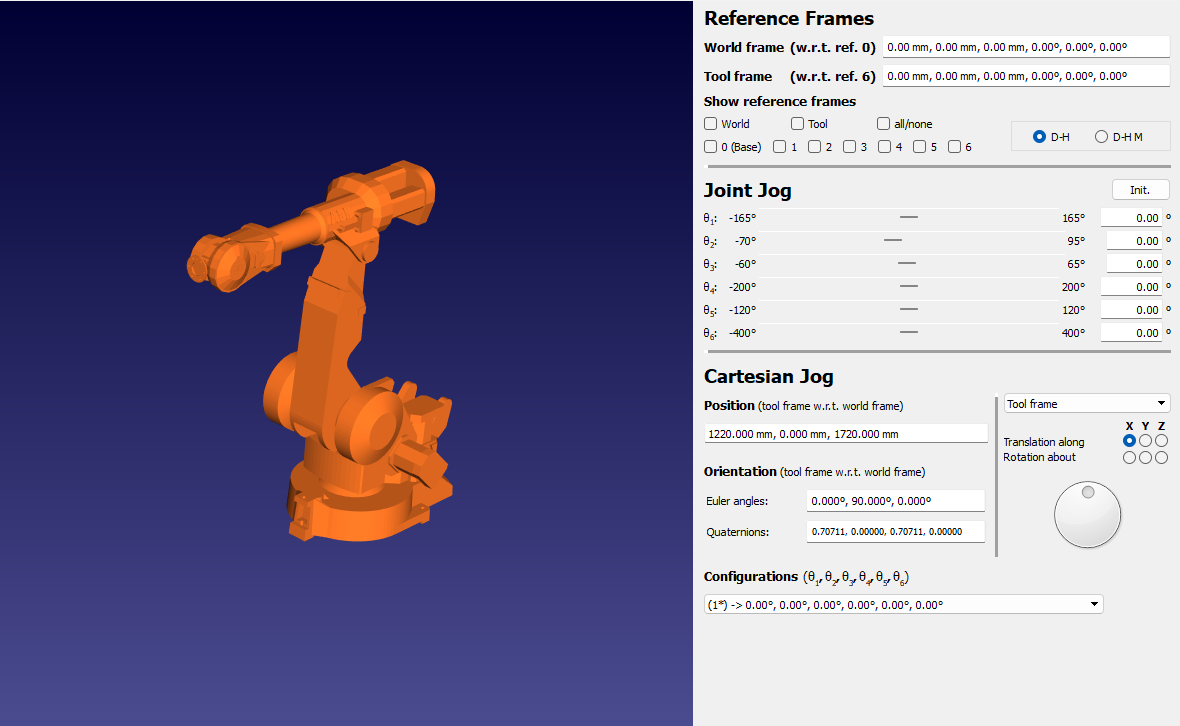


% Validação 2 (angulos teta3 = 45 e teta5 = -90):
teta1 = 0;
teta2 = 0;
teta3 = 45;
teta4 = 0;
teta5 = -90;
teta6 = 0;
fprintf('ABB IRB4400 - Validação 2 \n');

ABB IRB4400 - Validação 2 


fprintf('teta1 = %0.f ; ', teta1);

teta1 = 0 ; 

fprintf('teta2 = %0.f ; ', teta2);

teta2 = 0 ; 

fprintf('teta3 = %0.f ; ', teta3);

teta3 = 45 ; 

fprintf('teta4 = %0.f ; ', teta4);

teta4 = 0 ; 

fprintf('teta5 = %0.f ; ', teta5);

teta5 = -90 ; 

fprintf('teta6 = %0.f ', teta6);

teta6 = 0 

fprintf('\n\n');

disp('Matrizes parciais IRB4400 (Validação 2):')

Matrizes parciais IRB4400 (Validação 2):


% Matriz parcial 0-1:
IRB4400_2_dh_01 = denavit(200, -90, 680, teta1)

IRB4400_2_dh_01 =      1     0     0   200
     0     0     1     0
     0    -1     0   680
     0     0     0     1



% Matriz parcial 1-2:
IRB4400_2_dh_12 = denavit(890, 0, 0, teta2-90)

IRB4400_2_dh_12 = 4×4
     0     1     0     0
    -1     0     0  -890
     0     0     1     0
     0     0     0     1



% Matriz parcial 2-3:
IRB4400_2_dh_23 = denavit(150, -90, 0, teta3)

IRB4400_2_dh_23 = 4×4
    0.7071         0   -0.7071  106.0660
    0.7071         0    0.7071  106.0660
         0   -1.0000         0         0
         0         0         0    1.0000



% Matriz parcial 3-4:
IRB4400_2_dh_34 = denavit(0, 90, 880, teta4)

IRB4400_2_dh_34 = 4×4
     1     0     0     0
     0     0    -1     0
     0     1     0   880
     0     0     0     1



% Matriz parcial 4-5:
IRB4400_2_dh_45 = denavit(0, -90, 0, teta5)

IRB4400_2_dh_45 = 4×4
     0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1



% Matriz parcial 5-6:
IRB4400_2_dh_56 = denavit(0, 0, 140, teta6+180)

IRB4400_2_dh_56 = 4×4
    -1     0     0     0
     0    -1     0     0
     0     0     1   140
     0     0     0     1



% Matriz Final:
disp('Matriz Resultante ABB IRB4400 (Validação 2):')

Matriz Resultante ABB IRB4400 (Validação 2):


IRB4400_2_MR = IRB4400_2_dh_01 * IRB4400_2_dh_12 * IRB4400_2_dh_23 * IRB4400_2_dh_34 * IRB4400_2_dh_45 * IRB4400_2_dh_56

IRB4400_2_MR = 4×4
1.0e+03 *

    0.0007         0    0.0007    1.0273
         0    0.0010         0         0
   -0.0007         0    0.0007    1.1528
         0         0         0    0.0010